# Irányítástechnika

#### ZH2

**Nev: Nagy Richard**

**Index: 25223020**

### **1. feladat **– 8 p

**Tervezzen PID szabályzót az alábbi folyamat kompenzálására:**


$$P\left(s\right)=\frac{1}{\left(10s+1\right)\left(s+1\right)\left(0\ldotp 2s+1\right)}$$


** úgy, hogy biztosítsuk a kb. 60 fokos. Adjuk meg a minőségi jellemzők érékeit, valamint számítsuk ki és ábrázoljuk a kimenő jelet és a beavatkozó jelet egységugrás alapjel esetén. **

s=zpk('s');
P=1/(1+10*s)/(1+s)/(1+0.2*s);

Cpid=pidstd(47.7,0.0803,0.0189)

Cpid =
 
             1      1          
  Kp * (1 + ---- * --- + Td * s)
             Ti     s          

  with Kp = 47.7, Ti = 0.0803, Td = 0.0189
 
Continuous-time PID controller in standard form
Model Properties



[mag,phase,w] =  bode(Cpid*P);

kpid = margin(mag,phase-60,w);
Cpid = kpid*Cpid;
Tpid = feedback(Cpid*P,1);

y=step(Tpid);
ym=max(y)

ym = 1.0827

ys=dcgain(Tpid);
es=1-ys

es = -3.1086e-15


yovs=(ym-ys)/ys*100

yovs = 8.2726

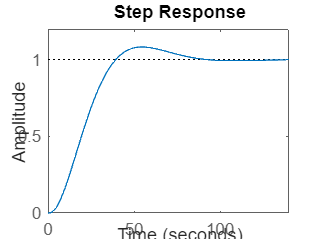


step(Tpid);

### **2. feladat **– 14 p

**Készítsen PI és PID szabályzást Ziegler-Nichols belengetéses módszerével az alábbi holtidővel rendelkező rendszerre:**


$$P\left(s\right)=\frac{0\ldotp 06}{9s+1}\;e^{-1\ldotp 5s}$$


**A megfelelő értékek megállapítása után a paramétereket az alábbi táblázat alapján válassza meg:**

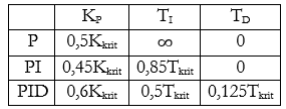

**Ábrával vagy a használt parancsokkal indokolja a leolvasott kritikus értékeket. Ábrázolja a kétféle szabályozott rendszer válaszát, és a szabályzások bemeneti zavarérzékenységét is!**

**Jellemezze a szabályozott rendszerek viselkedését (stabilitás, beállási idő, végérték, túllövés).**

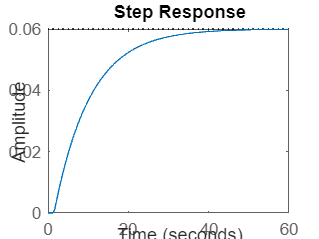

s=tf('s');
P=(0.06/(9*s+1))*exp(-1.5*s);
step(P)


[Gm,Pm,Wcg,Wcp]= margin(P);
Kkrit=Gm 

Kkrit = 167.8542

Tkrit=2*pi/Wcg 

Tkrit = 5.6427

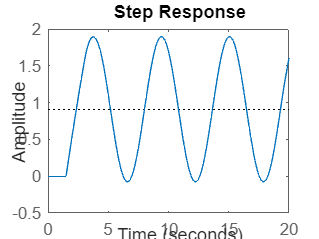

step(feedback(Kkrit*P,1),20)


Kp=0.45*Kkrit

Kp = 75.5344

Ti=0.85*Tkrit

Ti = 4.7963


Kp=0.45*Kkrit

Kp = 75.5344

Ti=0.85*Tkrit

Ti = 4.7963

C=pidstd(Kp,Ti,0)

C =
 
             1      1 
  Kp * (1 + ---- * ---)
             Ti     s 

  with Kp = 75.5, Ti = 4.8
 
Continuous-time PI controller in standard form
Model Properties


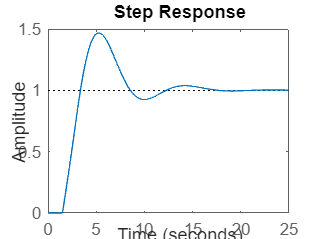

step(feedback(C*P,1))

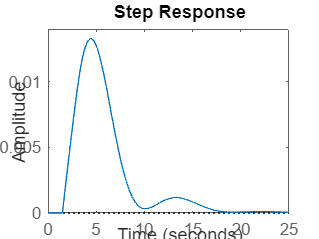

step(feedback(P,C))

stepinfo(feedback(C*P,1))

ans = struct with fields:
         RiseTime: 1.4710
    TransientTime: 16.0024
     SettlingTime: 16.0024
      SettlingMin: 0.9180
      SettlingMax: 1.4670
        Overshoot: 46.6960
       Undershoot: 0
             Peak: 1.4670
         PeakTime: 5.2981



Kp=0.45*Kkrit

Kp = 75.5344

Ti=0.85*Tkrit

Ti = 4.7963

Td=0.125*Tkrit;
C=pidstd(Kp,Ti,Td)

C =
 
             1      1          
  Kp * (1 + ---- * --- + Td * s)
             Ti     s          

  with Kp = 75.5, Ti = 4.8, Td = 0.705
 
Continuous-time PID controller in standard form
Model Properties


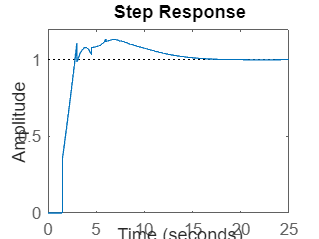

step(feedback(C*P,1))

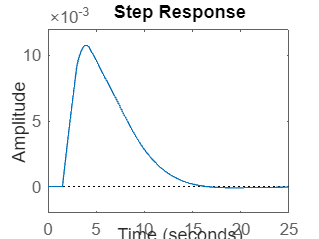

step(feedback(P,C))

stepinfo(feedback(C*P,1))

ans = struct with fields:
         RiseTime: 1.1063
    TransientTime: 13.9416
     SettlingTime: 13.9416
      SettlingMin: 0.9063
      SettlingMax: 1.1333
        Overshoot: 13.3331
       Undershoot: 0
             Peak: 1.1333
         PeakTime: 6.0000


**Válasz:**

**PI Szabalyzo adatok:**

** - stabil, periodikus, be allasi ido **`16.0024, tuloves 46.6960`

**PID Szabalyzo adatok:**

** - stabil, periodikus, be allasi ido **`13.9416, tuloves 13.3331`

### **3. feladat - 13 p**

**Írja fel az alábbi differenciálegyenletekkel leírható rendszer állapotteres alakját (a rendszer bemenete u, kimenete y, állapotváltozói pedig x1 és x2). Adja meg a rendszer pólusait! Vizsgálja meg az irányíthatóságát és megfigyelhetőségét, illetve kimeneti irányítóhatóságát! Hozza a modellt kanonikus alakra!**

***(mátrixok - 3 p, pólus - 0.5 p, Co - 1 p, Co*c 1p, Ob - 1 p, kanonikus - 1.5 p)***

A=[-6 -4; 2 0]

A =     -6    -4
     2     0


B=[-2; 2]

B =     -2
     2


C=[4 5]

C =      4     5


D=0

D = 0


eig(A)

ans =     -4
    -2


Co=ctrb(A,B)

Co =     -2     4
     2    -4



rank(Co)

ans = 1

det(Co)

ans = 0

rank(C*Co)

ans = 1


Ob=obsv(A,C)

Ob =      4     5
   -14   -16



rank(Ob)

ans = 2

[Ap Bp Cp Dp]=canon(A, B, C, D,'modal')

Ap =     -4     0
     0    -2


Bp =          0
   -5.6569


Cp =    -0.6708   -0.3536


Dp = 0

**Válasz:**

**A rendszer nem iranyithato, nem teljes ki meneti iranyithatosag, illetve a rendszer megfigyelheto**

**polusok -2, -4**

### **4. feladat - 15 p**

**Írja fel az alábbi P(s) rendszert állapotteres alakban! Adja meg a rendszer pólusait, majd teljes állapotvisszacsatolással helyezze át őket. Az új pólusok értékei az eredeti pólusok valós részeinek kétszeresei legyenek!** 


$$P\left(s\right)=\frac{5}{s^3 +{8\ldotp 5s}^2 +22\ldotp 5s+18}$$


s=zpk('s');
P=5/(s^3+8.5*s^2+22.5*s+18)

P =
 
           5
  -------------------
  (s+4) (s+3) (s+1.5)
 
Continuous-time zero/pole/gain model.
Model Properties



[A B C D]=ssdata(P)

A =    -1.5000    1.0000         0
         0   -3.0000    1.0000
         0         0   -4.0000


B =      0
     0
     2


C =     2.5000         0         0


D = 0

pc=[-3 -6 -8]

pc =     -3    -6    -8


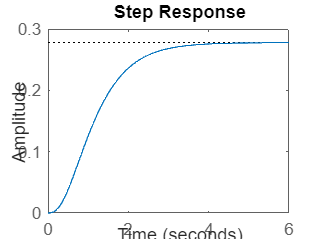


K=acker(A,B,pc);

Af=A-B*K;
Bf=B;
Cf=C-D*K;
Df=D;

step(A,B,C,D);

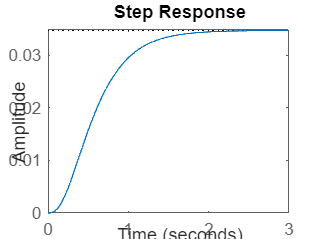

step(Af,Bf,Cf,Df)

**b) Hasonlítsa össze az eredeti és a kapott zárt rendszer átmeneti függvényét, beállási idejét, túllövését! **

H=ss(A,B,C,D)

H =
 
  A = 
         x1    x2    x3
   x1  -1.5     1     0
   x2     0    -3     1
   x3     0     0    -4
 
  B = 
       u1
   x1   0
   x2   0
   x3   2
 
  C = 
        x1   x2   x3
   y1  2.5    0    0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


step(H)

stepinfo(H)

ans = struct with fields:
         RiseTime: 1.8540
    TransientTime: 3.3783
     SettlingTime: 3.3783
      SettlingMin: 0.2507
      SettlingMax: 0.2777
        Overshoot: 0
       Undershoot: 0
             Peak: 0.2777
         PeakTime: 6.4242



H2=ss(Af,Bf,Cf,Df);

step(H2);

stepinfo(H2)

ans = struct with fields:
         RiseTime: 0.9270
    TransientTime: 1.6892
     SettlingTime: 1.6892
      SettlingMin: 0.0313
      SettlingMax: 0.0347
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0347
         PeakTime: 3.2121


**c) A megfelelő előerősítés alkalmazásával érje el hogy 1-be álljon be a zárt rendszer. Ábrázolja az így kapott rendszer egységugrásra adott válaszát.**

G=1/dcgain(Af,Bf,Cf,Df)

G = 28.8000


H3 = ss(Af,G*Bf,Cf,G*Df)

H3 =
 
  A = 
           x1      x2      x3
   x1    -1.5       1       0
   x2       0      -3       1
   x3  -43.88  -29.25   -12.5
 
  B = 
         u1
   x1     0
   x2     0
   x3  57.6
 
  C = 
        x1   x2   x3
   y1  2.5    0    0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


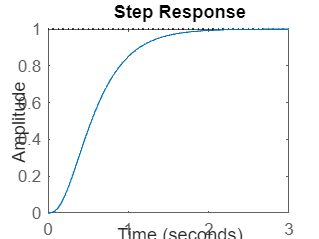

step(H3);

stepinfo(H3)

ans = struct with fields:
         RiseTime: 0.9270
    TransientTime: 1.6892
     SettlingTime: 1.6892
      SettlingMin: 0.9026
      SettlingMax: 0.9998
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9998
         PeakTime: 3.2121


**Válasz:**

**a megfelelo eloerosites g = 28.8000**

**rendszer adatai: be allasi ido 1.6892, tuloves 0, stabil aperiodikus **